% load('zzd.mat','zzd')
% load('t.mat','t')
% load('y_exprm.mat','y_exprm')

% save('zzd.mat','zzd')
% t = dt:dt:tf;
% save('t.mat','t')
% save('y_exprm.mat','y_exprm')

dist_ref  = [];
dist_expm = [];
% y_exprm__   = [y_exprm(1:end-1,:); y_exprm(end,:)];
% y_exprm__   = y_exprm(1:end-1,:);
% y_exprm__   = [zeros(1,3); y_exprm];
y_exprm__   = y_exprm;
zzd__       = [zeros(3,1), zzd];
t__         = [0, t];

for i = 1:size(zzd__,2)
    dist_ref  = [dist_ref,  norm(zzd__(:,i))];
    dist_expm = [dist_expm, norm(y_exprm__(i,1:2))];
end
dist_error = abs(dist_ref - dist_expm);


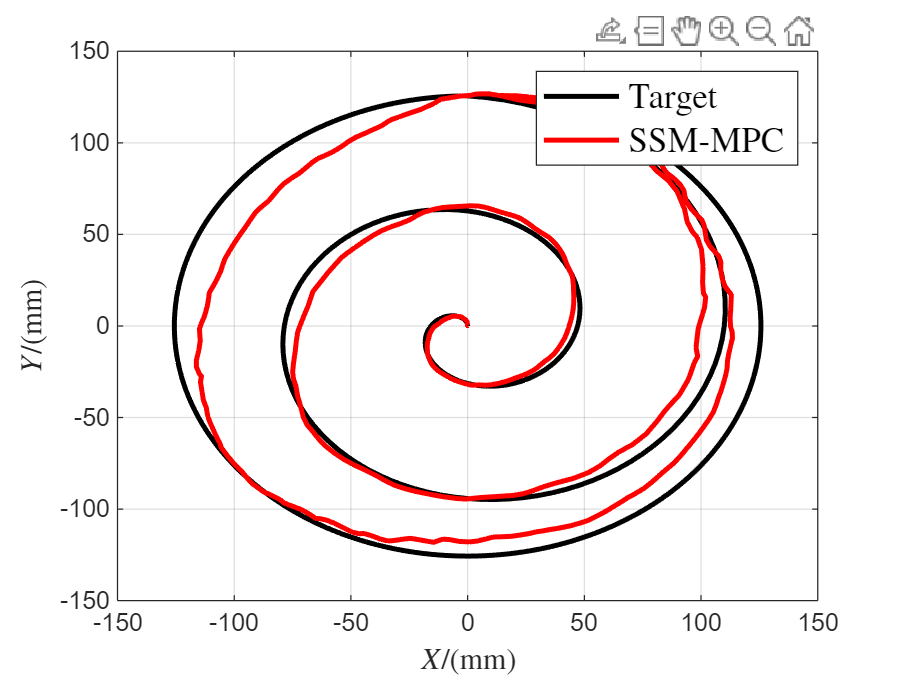

figure; hold on
plot(zzd__(1,:),zzd__(2,:),'k-',LineWidth=2,DisplayName='Target')
plot(-y_exprm__(:,1),y_exprm__(:,2),'r-',LineWidth=2,DisplayName='SSM-MPC')
grid on
xlabel('$X$/(mm)',Interpreter='latex',FontSize=12)
ylabel('$Y$/(mm)',Interpreter='latex',FontSize=12)
legend('show',Interpreter='latex',fontsize=14)
box on

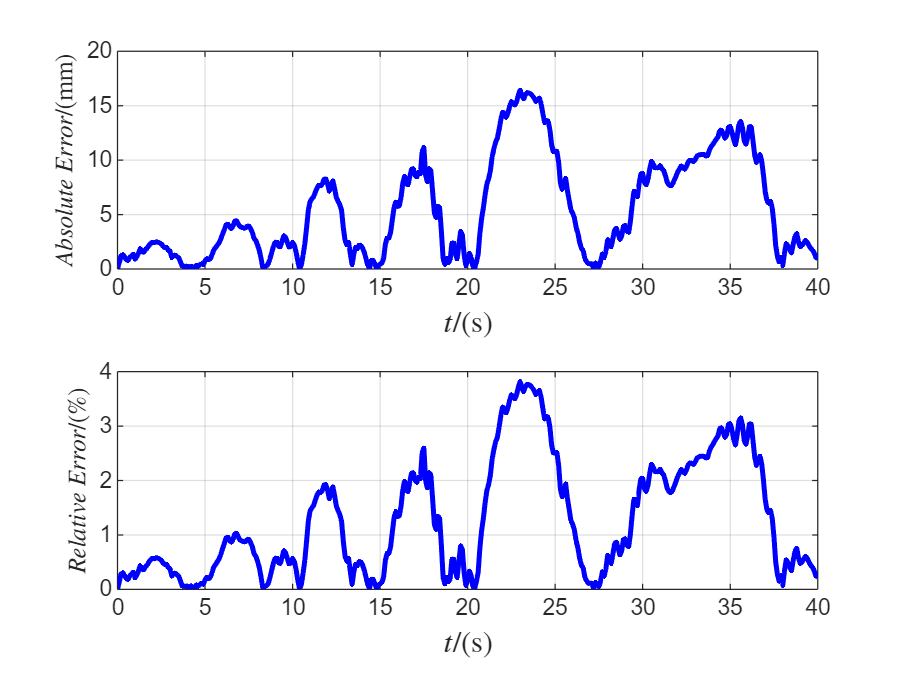

figure;
subplot(2,1,1)
plot(t__,dist_error,'b-',LineWidth=2)
xlim([t__(1),t__(end)])
grid on
xlabel('$t$/(s)',Interpreter='latex',FontSize=12)
ylabel('$Absolute$ $Error$/(mm)',Interpreter='latex',FontSize=10)

subplot(2,1,2)
plot(t__,dist_error/430.*100,'b-',LineWidth=2)
xlim([t__(1),t__(end)])
grid on
xlabel('$t$/(s)',Interpreter='latex',FontSize=12)
ylabel('$Relative$ $Error$/(\%)',Interpreter='latex',FontSize=10)

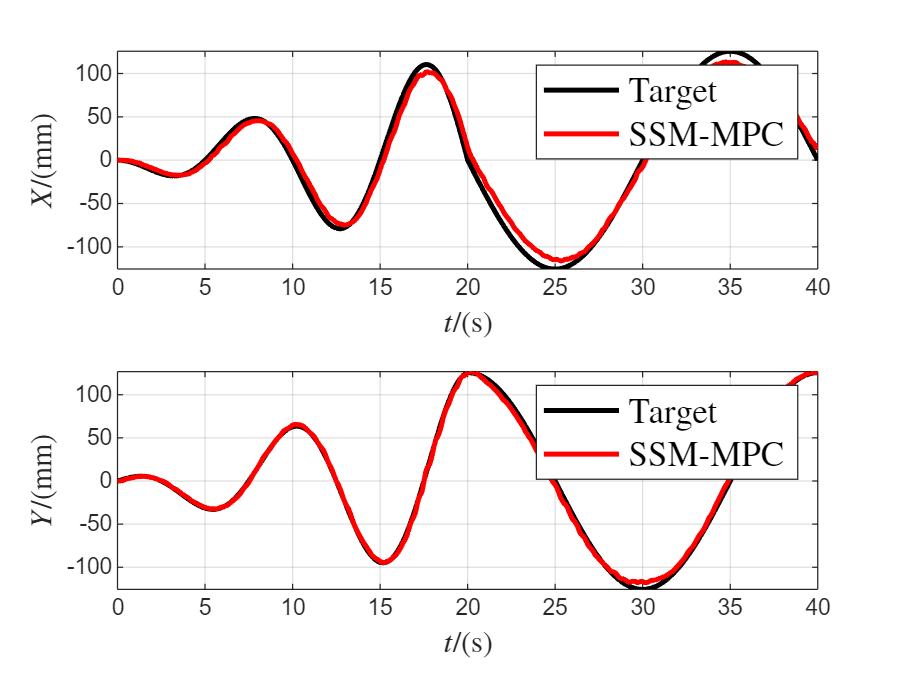

figure; 
subplot(2,1,1); hold on
plot(t__,zzd__(1,:),'k-',LineWidth=2,DisplayName='Target')
plot(t__,-y_exprm__(:,1),'r-',LineWidth=2,DisplayName='SSM-MPC')
% xlim([t(1),t(end)])
grid on
xlabel('$t$/(s)',Interpreter='latex',FontSize=12)
ylabel('$X$/(mm)',Interpreter='latex',FontSize=12)
legend('show',Interpreter='latex',fontsize=14)
box on

subplot(2,1,2); hold on
plot(t__,zzd__(2,:),'k-',LineWidth=2,DisplayName='Target')
plot(t__,y_exprm__(:,2),'r-',LineWidth=2,DisplayName='SSM-MPC')
% xlim([t(1),t(end)])
grid on
xlabel('$t$/(s)',Interpreter='latex',FontSize=12)
ylabel('$Y$/(mm)',Interpreter='latex',FontSize=12)
legend('show',Interpreter='latex',fontsize=14)
box on

% figure; hold on
% plot(t__,zzd__(2,:),'k-',LineWidth=2,DisplayName='Target')
% plot(t__,y_exprm__(:,2),'r-',LineWidth=2,DisplayName='SSM-MPC')
% % xlim([t(1),t(end)])
% grid on
% xlabel('$t$/(s)',Interpreter='latex',FontSize=12)
% ylabel('$Y$/(mm)',Interpreter='latex',FontSize=12)
% legend('show',Interpreter='latex',fontsize=14)
% box on

% figure; hold on
% % plot(t__,zzd__(3,:),'r-',LineWidth=2,DisplayName='Desired')
% plot(t__,y_exprm__(:,3),'r-',LineWidth=2,DisplayName='SSM-MPC')
% % xlim([t(1),t(end)])
% grid on
% xlabel('$t$/(s)',Interpreter='latex',FontSize=12)
% ylabel('$Z$/(mm)',Interpreter='latex',FontSize=12)
% legend('show',Interpreter='latex',fontsize=14)
% box on